# Punto 5

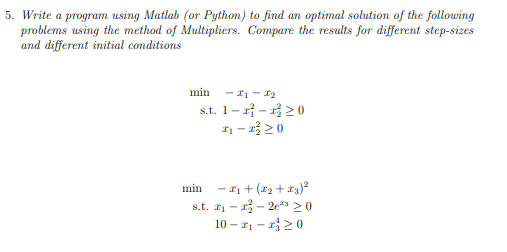

## 5.Método de Multiplicadores

El problema presentado utiliza el **método de multiplicadores** para optimizar una función objetivo bajo restricciones. En este caso, se optimizan dos funciones distintas mediante el uso de multiplicadores de Lagrange.

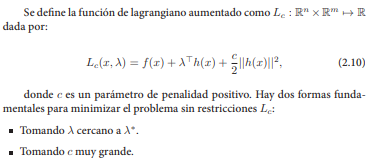

clc; clear; close all;

% Parámetros iniciales
alpha = [0.1, 0.001,0.002,0.0001]; % Tamaño del paso
tol = 1e-6;         % Tolerancia de convergencia
max_iter = 5000;    % Número máximo de iteraciones

% Inicialización de variables
x_init = [-1; 1];     % Valores iniciales de x1 y x2
mu_init = [0; 0];    % Multiplicadores iniciales para las restricciones

% Funciones
f = @(x) -x(1) - x(2); % Función objetivo
grad_f = @(x) [-1; -1];     % Gradiente de f
g = @(x) [x(1)^2 + x(2)^2 - 1; -x(1) + x(2)]; % Restricciones
grad_g = @(x) [2*x(1), -1; 2*x(2), 1]; % Gradientes de restricciones


% Llamada a la función de optimización
[x_opt, mu_opt, iter] = optimizar(alpha(1), tol, max_iter, x_init, mu_init, f, grad_f, g, grad_g);
% Mostrar resultados
fprintf('--- Resultados ---\n');

--- Resultados ---


fprintf('x* = [%f, %f]\n', x_opt(1), x_opt(2));

x* = [0.707101, 0.707101]


fprintf('mu* = [%f, %f]\n', mu_opt(1), mu_opt(2));

mu* = [0.707111, 0.000000]


fprintf('Número de iteraciones: %d\n', iter);

Número de iteraciones: 160


[x_opt, mu_opt, iter] = optimizar(alpha(2), tol, max_iter, x_init, mu_init, f, grad_f, g, grad_g);
% Mostrar resultados
fprintf('--- Resultados ---\n');

--- Resultados ---


fprintf('x* = [%f, %f]\n', x_opt(1), x_opt(2));

x* = [0.748228, 0.734095]


fprintf('mu* = [%f, %f]\n', mu_opt(1), mu_opt(2));

mu* = [0.700366, 0.000000]


fprintf('Número de iteraciones: %d\n', iter);

Número de iteraciones: 5000


[x_opt, mu_opt, iter] = optimizar(alpha(3), tol, max_iter, x_init, mu_init, f, grad_f, g, grad_g);
% Mostrar resultados
fprintf('--- Resultados ---\n');

--- Resultados ---


fprintf('x* = [%f, %f]\n', x_opt(1), x_opt(2));

x* = [0.706118, 0.706107]


fprintf('mu* = [%f, %f]\n', mu_opt(1), mu_opt(2));

mu* = [0.707396, 0.000000]


fprintf('Número de iteraciones: %d\n', iter);

Número de iteraciones: 5000


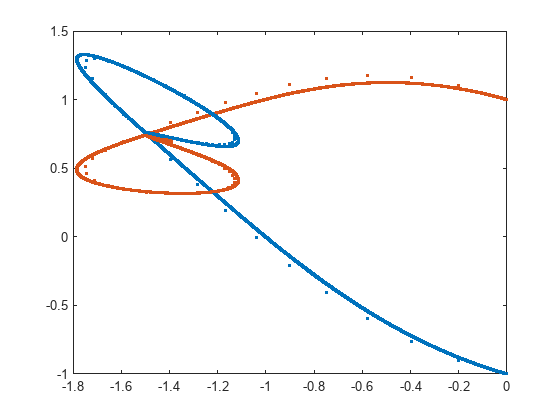

[x_opt, mu_opt, iter] = optimizar(alpha(4), tol, max_iter, x_init, mu_init, f, grad_f, g, grad_g);

% Mostrar resultados
fprintf('--- Resultados ---\n');

--- Resultados ---


fprintf('x* = [%f, %f]\n', x_opt(1), x_opt(2));

x* = [-0.167151, 1.049422]


fprintf('mu* = [%f, %f]\n', mu_opt(1), mu_opt(2));

mu* = [0.319557, 0.856783]


fprintf('Número de iteraciones: %d\n', iter);

Número de iteraciones: 5000


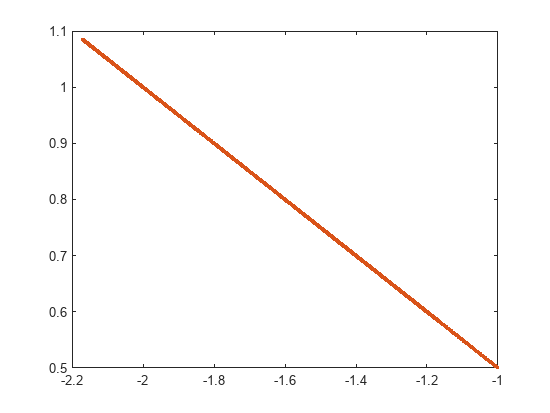

[x_opt, mu_opt, iter] = optimizar(alpha(2), tol, max_iter, [0.5,0.5], mu_init, f, grad_f, g, grad_g);

% Mostrar resultados
fprintf('--- Resultados ---\n');

--- Resultados ---


fprintf('x* = [%f, %f]\n', x_opt(1), x_opt(2));

x* = [0.708622, 0.708622]


fprintf('mu* = [%f, %f]\n', mu_opt(1), mu_opt(2));

mu* = [0.731306, 0.000000]


fprintf('Número de iteraciones: %d\n', iter);

Número de iteraciones: 5000


clc; clear; close all;

% Parámetros iniciales
alpha = [0.1, 0.001,0.002,0.0001]; % Tamaño del paso
tol = 1e-6;          % Tolerancia de convergencia
max_iter = 5000;     % Número máximo de iteraciones

% Inicialización de variables
x_init = [-1; 1; 0]; % Valores iniciales de x1, x2, x3
mu_init = [0; 0];   % Multiplicadores iniciales para las restricciones

% Función objetivo y gradiente
f2 = @(x) [-x(1) + (x(2) + x(3))^2]; % Función objetivo
grad_f2 = @(x) [-1; 2*x(2) + 2*x(3); 2*x(2) + 2*x(3)]; % Gradiente de f2

% Restricciones y sus gradientes
g2 = @(x) [-x(1) + x(2)^2 + 2*exp(x(3)); -10 + x(1) + x(3)^4]; % Restricciones
grad_g2 = @(x) [ ...
    -1, 1; ...           % Derivadas de g1 y g2 respecto a x1
    2*x(2), 0; ...        % Derivadas de g1 y g2 respecto a x2
    2*exp(x(3)), 4*x(3)^3 ... % Derivadas de g1 y g2 respecto a x3
];


% Llamada a la función optimizar
[x_opt, mu_opt, iter] = optimizar(alpha(1), tol, max_iter, x_init, mu_init, f2, grad_f2, g2, grad_g2);
% Mostrar resultados
fprintf('--- Resultados ---\n');

--- Resultados ---


fprintf('x* = [%f, %f, %f]\n', x_opt(1), x_opt(2), x_opt(3));

x* = [10.822258, 0.022636, -0.022630]


fprintf('mu* = [%f, %f]\n', mu_opt(1), mu_opt(2));

mu* = [0.000000, 0.722014]


fprintf('Número de iteraciones: %d\n', iter);

Número de iteraciones: 5000


[x_opt, mu_opt, iter] = optimizar(alpha(2), tol, max_iter, x_init, mu_init, f2, grad_f2, g2, grad_g2);
% Mostrar resultados
fprintf('--- Resultados ---\n');

--- Resultados ---


fprintf('x* = [%f, %f, %f]\n', x_opt(1), x_opt(2), x_opt(3));

x* = [6.140929, 0.639289, -0.639291]


fprintf('mu* = [%f, %f]\n', mu_opt(1), mu_opt(2));

mu* = [0.000000, 0.000000]


fprintf('Número de iteraciones: %d\n', iter);

Número de iteraciones: 5000


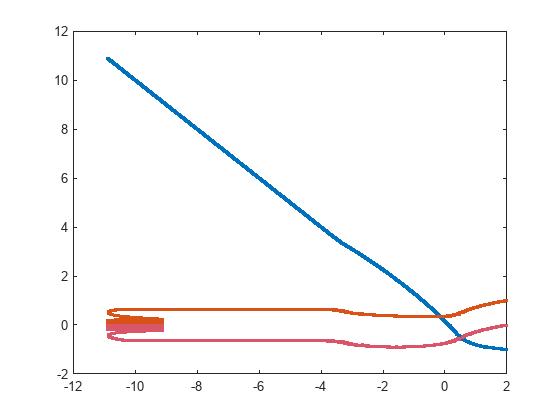


[x_opt, mu_opt, iter] = optimizar(alpha(3), tol, max_iter, x_init, mu_init, f2, grad_f2, g2, grad_g2);

% Mostrar resultados
fprintf('--- Resultados ---\n');

--- Resultados ---


fprintf('x* = [%f, %f, %f]\n', x_opt(1), x_opt(2), x_opt(3));

x* = [10.814728, 0.564150, -0.492277]


fprintf('mu* = [%f, %f]\n', mu_opt(1), mu_opt(2));

mu* = [0.000000, 0.690521]


fprintf('Número de iteraciones: %d\n', iter);

Número de iteraciones: 5000



[x_opt, mu_opt, iter] = optimizar(alpha(4), tol, max_iter, x_init, mu_init, f2, grad_f2, g2, grad_g2);
% Mostrar resultados
fprintf('--- Resultados ---\n');
fprintf('x* = [%f, %f, %f]\n', x_opt(1), x_opt(2), x_opt(3));
fprintf('mu* = [%f, %f]\n', mu_opt(1), mu_opt(2));
fprintf('Número de iteraciones: %d\n', iter);

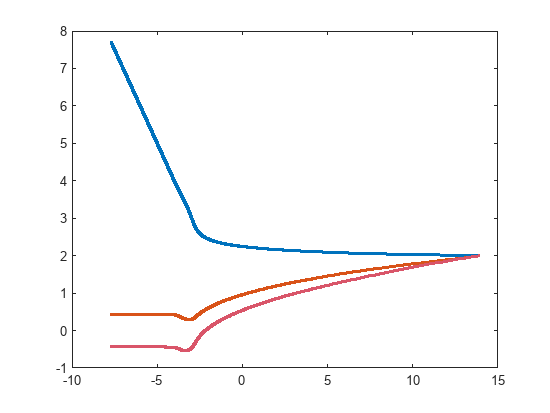

[x_opt, mu_opt, iter] = optimizar(alpha(2), tol, max_iter, [2,2,2], mu_init, f2, grad_f2, g2, grad_g2);

% Mostrar resultados
fprintf('--- Resultados ---\n');

--- Resultados ---


fprintf('x* = [%f, %f, %f]\n', x_opt(1), x_opt(2), x_opt(3));

x* = [7.685155, 0.436779, -0.436779]


fprintf('mu* = [%f, %f]\n', mu_opt(1), mu_opt(2));

mu* = [0.000000, 0.000000]


fprintf('Número de iteraciones: %d\n', iter);

Número de iteraciones: 5000


El proceso de optimización sigue los siguientes pasos:

- **Lagrangiana y Gradientes**: Se forma la Lagrangiana combinando la función objetivo y las restricciones con los multiplicadores μ1 y μ2.

- **Desarrollo del Método de Multiplicadores**: Se realiza una actualización iterativa de las variables x1,x2,x3 y de los multiplicadores utilizando el gradiente descendente sobre la Lagrangiana.

- **Visualización y Convergencia**: En cada iteración, se muestra el comportamiento de la optimización, y se verifica si se ha alcanzado la convergencia.

function [x_opt, mu_opt, iter] = optimizar(alpha, tol, max_iter, x_init, mu_init, f, grad_f, g, grad_g)
    % Parámetros iniciales
    x = x_init; % Valores iniciales de x
    mu = mu_init; % Valores iniciales de los multiplicadores

    % Iteraciones
    for i = 1:max_iter
        % Evaluar gradiente de la función objetivo en x
        grad_f_val = grad_f(x);

        % Evaluación de gradiente de restricciones
        grad_gx = grad_g(x);
        
         % Asegurarse de que mu es un vector columna
        mu = mu(:); % Convertir a vector columna si no lo es

        % Gradiente de la Lagrangiana
        grad_L = grad_f_val + grad_gx * mu;
        
        % Actualización de x usando gradiente descendente
        x = x - alpha * grad_L;

        % Actualización de los multiplicadores
        g_val = g(x); % Evaluar restricciones

        mu = max(0, mu + alpha * g_val); % Proyección positiva
        
        % Visualización
        plot(f(x), x(1), '.', 'LineWidth', 1, 'Color', '#0072BD');
        hold on;
        plot(f(x), x(2), '.', 'LineWidth', 1, 'Color', '#D95319');
        hold on
        % Verificar si hay una tercera variable y plotearla
        if length(x) == 3
        plot(f(x), x(3), '.', 'LineWidth', 1, 'Color', '#D95569');
        end
        pause(0.1)
        hold on;

        % Criterio de convergencia
        if norm(grad_L) < tol
            break;
        end
    end

    % Resultados finales
    x_opt = x;
    mu_opt = mu;
    iter = i;
end

#### Análisis

**1.Impacto en la Convergencia****:**

- **Para alpha = 0.1**: Se espera una convergencia relativamente rápida, pero podría ser inestable. El algoritmo podría no encontrar la solución óptima si el paso es demasiado grande y "salta" sobre el óptimo.

- **Para alpha = 0.001 y 0.002**: Estos valores son más pequeños, lo que debería permitir una convergencia más estable y precisa. Sin embargo, las iteraciones serán más numerosas, lo que implica un tiempo de ejecución más largo.

- **Para alpha = 0.0001**: Este valor muy pequeño podría resultar en una convergencia extremadamente lenta, ya que las actualizaciones de las variables son muy pequeñas en cada iteración, lo que alarga el proceso de optimización.

**2. Impacto de los Puntos Iniciales**

Los puntos iniciales tienen un impacto significativo en la velocidad de convergencia, especialmente en problemas no convexos. El algoritmo utiliza los puntos iniciales (x1,x2 o x1,x2,x3) para comenzar la búsqueda de la solución óptima. Los resultados de la optimización pueden variar dependiendo de si el punto inicial está cerca o lejos de la solución óptima.

**Punto Inicial en el Primer Caso****:**

En este caso, el punto inicial es [−1,1]. Como la función objetivo y las restricciones son relativamente simples, el algoritmo debería converger rápidamente hacia la solución óptima, dependiendo del valor de alpha.

**Punto Inicial en el Segundo Caso****:**

Aquí el punto inicial es [−1,1,0]. Con tres variables, el espacio de búsqueda es más complejo, y el comportamiento de la optimización puede depender más del valor de alpha. Si el punto inicial no está cerca de la solución óptima, se necesitarán más iteraciones.